# Assignment4_Sequence Classification

In this assignment, you will 

- Perform data preprocessing on the data with different sequence lengths.

- Create a LSTM network.

- Compare the results and see performance improvement.

시퀀스 길이가 다른 데이터에 대해 데이터 전처리를 수행합니다.

LSTM 네트워크를 만듭니다.

결과를 비교하고 성능 개선을 확인하세요.

## 0. Loading Data

This contains 470 recordings of the Flute, Cello, and Piano, stored in cell arrays, along with their correct labels stored in categoricals. There is also a sampling rate of the recordings.

여기에는 categoricals에 저장된 올바른 레이블과 함께 셀 배열에 저장된 470개의 플루트, 첼로 및 피아노 녹음이 포함됩니다. 녹음의 샘플링 속도도 있습니다.

**Note that the data consists of different sequence lengths.**

load("classify3InstrumentsData_SequenceLength.mat")
whos

  Name          Size              Bytes  Class                           Attributes

  XTest        90x1             2364168  cell                                      
  XTrain      380x1             9913952  cell                                      
  YTest        90x1                 434  categorical                               
  YTrain      380x1                 724  categorical                               
  fs            1x1                   8  double                                    
  net           1x1              342595  SeriesNetwork                             
  opts          1x1                 287  nnet.cnn.TrainingOptionsADAM              



size(XTrain)

ans =    380     1


categories(YTrain)

ans = 3×1 cell 배열
    {'Flute'}
    {'Cello'}
    {'Piano'}


# 3.1. Without data preprocessing

## 1. Creating the Network

###     Assemble network layers

- Start with a sequence input layer with a single input node, since these sequences only have one features. 

- Follow with a BiLSTM layer with 100 nodes. Output only the last time step of each recording sample being classified. 

- End with a fully connected layer with one node for each instrument, a softmax layer, and a classificationLayer.

- 단일 입력 노드가 있는 시퀀스 입력 레이어로 시작하세요. 이러한 시퀀스에는 기능이 하나만 있기 때문입니다.

- 100개의 노드가 있는 BiLSTM 레이어를 따릅니다. 분류되는 각 녹음 샘플의 마지막 시간 간격만 출력합니다.

- 각 기기에 대해 하나의 노드, 소프트맥스 레이어 및 classificationLayer가 있는 완전히 연결된 레이어로 끝납니다.

layers = [sequenceInputLayer(1);
    bilstmLayer(100, "OutputMode","last");
    fullyConnectedLayer(3);
    softmaxLayer()
    classificationLayer()]

layers =   다음 계층을 포함한 5×1 Layer 배열:

     1   ''   시퀀스 입력   시퀀스 입력 (차원 1개)
     2   ''   BiLSTM      BiLSTM (은닉 유닛 100개)
     3   ''   완전 연결     3 완전 연결 계층
     4   ''   소프트맥스    소프트맥스
     5   ''   분류 출력     crossentropyex

## 2. The Trained Network

It takes long to train a LSTM network. Use the trained network. This network was trained with the following options.

- Adam optimizer

- Maximum number of epochs: 250

- Gradient threshold: 1

- Learn rate schedule: piecewise

- Initial learning rate: 0.005

- Learn rate drop period: 60

- Plot the training progress

아담 옵티마이저

최대 에포크 수: 250

기울기 임계값: 1

요금표 알아보기: 조각별

초기 학습률: 0.005

학습률 하락 기간: 60

훈련 진행 상황 플롯

load("network_noDP.mat")
whos

  Name          Size              Bytes  Class                           Attributes

  XTest        90x1             2364168  cell                                      
  XTrain      380x1             9913952  cell                                      
  YTest        90x1                 434  categorical                               
  YTrain      380x1                 724  categorical                               
  ans           3x1                 342  cell                                      
  fs            1x1                   8  double                                    
  layers        5x1                2328  nnet.cnn.layer.Layer                      
  net           1x1              342595  SeriesNetwork                             
  opts          1x1                 287  nnet.cnn.TrainingOptionsADAM              



opts = trainingOptions("adam","Plots","training-progress","MaxEpochs",250,...
    "GradientThreshold",1,"LearnRateSchedule","piecewise","InitialLearnRate",0.005,...
    "LearnRateDropPeriod",60,"LearnRateDropFactor",0.1)

opts =   TrainingOptionsADAM - 속성 있음:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0050
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 60
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: 1
                       MaxEpochs: 250
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
  

% net = trainNetwork(XTrain, YTrain, layers, opts)

## 3. Evaluating the Network 

### 3.1. Predict the test labels

pred = classify(net, XTest)

pred = 90×1 categorical 배열
     Cello 
     Cello 
     Cello 
     Piano 
     Cello 
     Cello 
     Piano 
     Cello 
     Cello 
     Cello 
     Cello 
     Piano 
     Piano 
     Piano 
     Piano 
     Cello 
     Piano 
     Piano 
     Piano 
     Piano 
     Cello 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 


### 3.2. Calculate the prediction accuracy

Acc = nnz(pred == YTest)/numel(YTest)

Acc = 0.6000

### 3.3. Display a confusion chart

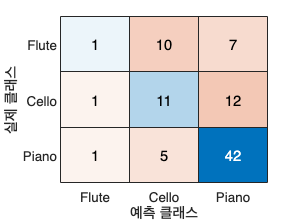

confusionchart(YTest, pred)

# 3.2. With data preprocessing

## 1. Data Preprocessing

### 1.1. Sort the training data

Get the sequence lengths of the training data for each observation.

numobservations = height(XTrain)

numobservations = 380

sequenceLength = zeros(1, numobservations)

sequenceLength =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Sort the training data by sequence length and update the training data.

for i = 1:numobservations
    sequenceData = XTrain{i};
    sequenceLength(i) = size(sequenceData, 2);
end
[sequenceLength_sorted, idx]= sort(sequenceLength, "ascend") %오름차순

sequenceLength_sorted =         3036        3036        3036        3036        3036        3036        3036        3036        3036        3036        3036        3036        3036        3036        3036        3036        3036        3036        3036        3036        3041        3041        3041        3041        3041        3041        3041        3041        3041        3041        3041        3041        3041        3041        3041        3041        3041        3041        3041        3041        3058        3058        3058        3058        3058        3058        3058        3058        3058        3058


idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


XTrain = XTrain(idx)

XTrain = 380×1 cell 배열
    {[      0.0499 0.0510 0.0499 0.0526 0.0537 0.0537 0.0520 0.0454 0.0472 0.0537 0.0538 0.0520 0.0530 0.0527 0.0554 0.0598 0.0577 0.0583 0.0580 0.0540 0.0568 0.0570 0.0551 0.0556 0.0495 0.0456 0.0492 0.0536 0.0569 0.0575 0.0576 0.0602 0.0612 0.0583 0.0562 0.0556 0.0554 0.0558 0.0568 0.0575 0.0554 0.0535 0.0506 0.0482 0.0526 0.0553 0.0527 0.0534 0.0557 0.0575 0.0593 0.0578 0.0576 0.0559 0.0522 0.0539 0.0536 0.0508 0.0532 0.0518 0.0510 0.0566 0.0569 0.0568 0.0597 0.0600 0.0591 0.0550 0.0505 0.0495 0.0514 0.0479 0.0388 0.0402 0.0454 0.0463 0.0484 0.0467 0.0466 0.0513 0.0520 0.0494 0.0481 0.0482 0.0482 0.0493 0.0515 0.0528 0.0485 0.0476 0.0534 0.0533 0.0542 0.0607 0.0621 0.0607 0.0633 0.0615 0.0574 0.0597 0.0607 0.0583 0.0566 0.0553 0.0564 0.0583 0.0592 0.0578 0.0551 0.0592 0.0618 0.0598 0.0640 0.0610 0.0556 0.0556 0.0515 0.0476 0.0487 0.0473 0.0426 0.0443 0.0486 0.0516 0.0538 0.0526 0.0493 0.0493 0.0520 0.0512 0.0477 0.0478 0.0471 0.0453 0.0456 0.0461 0.0473 0.0507

YTrain = YTrain(idx)

YTrain = 380×1 categorical 배열
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 


### 1.2. Display the sorted data

View the sorted sequence lengths in a bar chart.

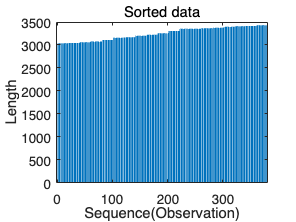

figure
bar(sequenceLength_sorted)
% ylim([0,15])
xlabel("Sequence(Observation)")
ylabel("Length")
title("Sorted data")

## 2. Creating LSTM Network

Use the same LSTM network created above(3.1.1).

## 3. The Trained Network

Use the trained network. This network was trained with the following options.

**Note that all training options are the same as in 3.1.2 except the shuffle option.**

- Adam optimizer

- Maximum number of epochs: 250

- Gradient threshold: 1

- Learn rate schedule: piecewise

- Initial learning rate: 0.005

- Learn rate drop period: 60

- **Shuffle: never**

- Plot the training progress

load("network.mat")
whos

  Name                         Size                Bytes  Class                           Attributes

  Acc                          1x1                     8  double                                    
  XTest                       90x1               2364168  cell                                      
  XTrain                     380x1               9913952  cell                                      
  YTest                       90x1                   434  categorical                               
  YTrain                     380x1                   724  categorical                               
  ans                          3x1                   342  cell                                      
  fs                           1x1                     8  double                                    
  i                            1x1                     8  double                                    
  idx                          1x380                3040  double                          

opts = trainingOptions("adam","Plots","training-progress","Shuffle","never",...
    "InitialLearnRate",0.005,"LearnRateSchedule","piecewise","LearnRateDropPeriod",60,...
    "LearnRateDropFactor",0.1,"GradientThreshold",1,"MaxEpochs",250,...
    "MiniBatchSize",128)

opts =   TrainingOptionsADAM - 속성 있음:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0050
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 60
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: 1
                       MaxEpochs: 250
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'never'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
 


% net = trainNetwork(XTrain, YTrain, layers, opts)

## 4. Evaluating network

The trained network used mini-batches of sequences of similar length. Ensure that the test data is organized in the same way. Sort the test data by sequence length.

훈련된 네트워크는 비슷한 길이의 시퀀스 미니 배치를 사용했습니다. 테스트 데이터가 동일한 방식으로 구성되어 있는지 확인하십시오. 시퀀스 길이를 기준으로 테스트 데이터를 정렬합니다.

### 4.1. Sort the test data

Get the sequence lengths of the test data for each observation.

numobservations = height(XTest)

numobservations = 90

sequenceLength = zeros(1, numobservations)

sequenceLength =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Sort the test data by sequence length and update the test data.

for i = 1:numobservations
    sequenceData = XTest{i};
    sequenceLength(i) = size(sequenceData, 2);
end

[sequenceLength_sorted, idx] = sort(sequenceLength, "ascend")

sequenceLength_sorted =         3089        3089        3089        3089        3089        3089        3089        3089        3089        3089        3089        3089        3089        3089        3089        3089        3089        3089        3089        3145        3145        3145        3145        3145        3145        3145        3145        3145        3145        3145        3145        3145        3145        3145        3145        3145        3145        3145        3145        3349        3349        3349        3349        3349        3349        3349        3349        3349        3349        3349


idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


XTest = XTest(idx)

XTest = 90×1 cell 배열
    {[      -0.0027 6.2660e-04 -0.0094 -0.0043 -0.0048 -0.0022 2.5140e-04 0.0105 0.0120 4.5949e-04 -0.0040 -0.0162 -0.0055 0.0126 -0.0072 -8.5624e-04 0.0199 0.0020 -0.0056 -0.0094 -0.0111 0.0088 0.0023 -0.0078 0.0135 0.0035 -2.5242e-04 0.0052 -0.0238 -0.0028 0.0197 -0.0104 1.3280e-04 0.0103 -0.0039 0.0124 -0.0147 -0.0191 0.0253 -0.0045 -0.0110 0.0176 -0.0105 0.0069 0.0129 -0.0312 0.0095 0.0088 -0.0181 0.0235 -0.0091 -0.0125 0.0404 -0.0265 -0.0249 0.0319 -0.0198 0.0087 0.0145 -0.0303 0.0363 6.3220e-04 -0.0459 0.0370 -0.0149 -0.0178 0.0522 -0.0415 2.2441e-04 0.0500 -0.0569 0.0115 0.0199 -0.0496 0.0622 -0.0113 -0.0545 0.0823 -0.0379 -0.0388 0.0683 -0.0638 0.0177 0.0621 -0.0894 0.0511 0.0210 -0.0820 0.0846 -0.0382 -0.0536 0.1245 -0.0768 -0.0287 0.0990 -0.1059 0.0394 0.0509 -0.1202 0.1113 0.0053 -0.1105 0.1298 -0.0692 -0.0530 0.1435 -0.1315 0.0150 0.1207 -0.1521 0.0788 0.0392 -0.1459 0.1559 -0.0431 -0.1137 0.1836 -0.1086 -0.0365 0.1574 -0.1728 0.0535 0.1088 -0.1883 0.13

YTest = YTest(idx)

YTest = 90×1 categorical 배열
     Flute 
     Flute 
     Flute 
     Flute 
     Flute 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 


### 4.2. Predict the test labels

predTest = classify(net, XTest, "MiniBatchSize", 128, "SequenceLength", 'longest') %오름차순 = longest, 내림차순 = shortest

predTest = 90×1 categorical 배열
     Flute 
     Flute 
     Flute 
     Flute 
     Flute 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Cello 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 


### 4.3. Calculate the prediction accuracy

Acc = nnz(predTest == YTest)/numel(YTest)

Acc = 0.9222

### 4.4. Display a confusion chart

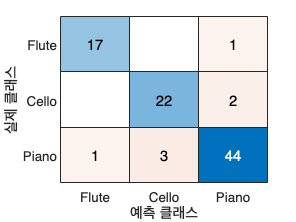

confusionchart(YTest, predTest)